# Memoria de ejercicios puntuables de localización

Se entregará un único archivo comprimido (PR2.zip), conteniendo una única memoria en PDF (memoria_cypr_pr2.pdf) con indicación de los ejercicios que se han resuelto, comentarios sobre el mismo y capturas de pantalla que justifiquen el funcionamiento (no añadir el código a la memoria). Finalmente, un archivo Matlab en formato live_script (*.mlx) por cada ejercicio realizado.

- Alumno: Ricardo Panero Lamothe

- Asignatura: Control y Programación de Robots

- Curso: 2022/23

- Plazo de entrega: 12-dic-2022

## Ejercicio puntuable - LSE

## Ejercicio puntuable - FP

### Implementación del filtro de partículas

#### a) Medida sensoríal

Utilizando un mapa de landmarks como el empleado en los  ejercicios anteriores, implementa ahora una función que tome como entrada la  pose del robot, seleccione aleatoriamente un solo landmark de entre todos los  disponibles, y devuelva la observación del sensor a dicho landmark. Dicha  observación estará compuesta por las medidas de distancia y ángulo entre el robot  y el landmark seleccionado, afectadas por el ruido del sensor siguiendo su modelo  de ruido en base a la matriz de covarianza

% Inicializamos el mapa
close all;
clear all;
Mapa={};
Mapa.nLandmarks = 7;
Mapa.Size = 20;      
Mapa.Landmarks = crear_landmarks(Mapa);

% Inicializamos el robt
Robot={};
Robot.xTrue=[5 -5 pi/2]' % posición inicial del robot
Robot.xOdom=[5 -5 pi/2]';
Robot.CovSensor = diag([0.5^2 (0.5*pi/180)^2]);

% Leemos la observación 
observacion=leer_sensor(Mapa, Robot)

#### b) Acción de control

Programa el movimiento del robot como en prácticas  anteriores, buscando realizar un cuadrado de lado 10m, y estando las acciones de  control afectadas por cierto ruido aleatorio en base a la matriz de covarianza de acciones

En este punto, tendremos la pose odométrica (xOdom), es decir, donde el robot  cree que está, la pose real (xTrue), es decir, donde el robot está realmente (esta  pose, aunque la simularemos en este ejercicio, es desconocida por el robot y es la  que se quiere estimar con el sistema de localización), y deberemos generar un  número de N poses candidatas (samples), dadas por las partículas del filtro que  estamos implementando. Considerar N=100.

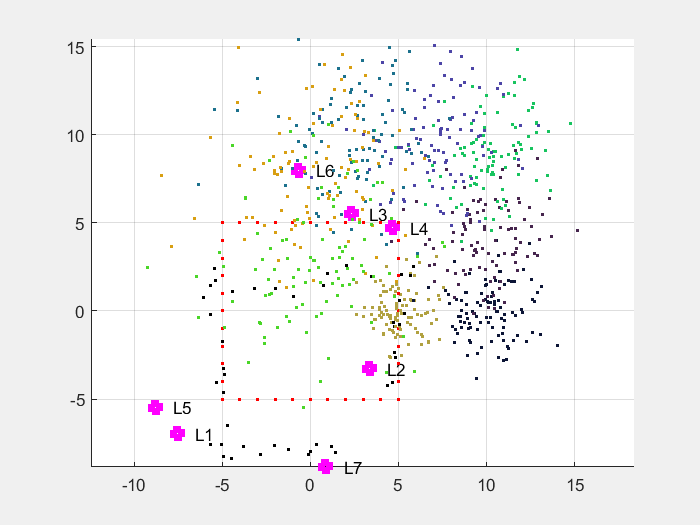

%Robot.plot = drawrobot(Robot.xTrue, 'b');
Robot.u_avance = [1 0 0]'; % accion de avance sin ruido
Robot.u_giro = [0 0 pi/2]'; % acción de giro a la izquierda
Robot.CovU = diag([0.5^2 0.5^2 (0.5*pi/180)^2]); % covarianzas
Robot.Particles = 100;
Robot.xProb = zeros(3, Robot.Particles);

for i=1:44
    if mod(i,11)==0
        u=Robot.u_giro;
    else
        u=Robot.u_avance;
    end
    % posición odométrica
    Robot.xOdom=pose_comp(Robot.xOdom, u);
    plot(Robot.xOdom(1), Robot.xOdom(2), 'r.');

    % posición real afectada por el ruido
    noise=sqrt(Robot.CovU)*randn(3, 1);
    Robot.xTrue=pose_comp(Robot.xTrue, pose_comp(u, noise));
    plot(Robot.xTrue(1), Robot.xTrue(2), 'k.');
    
    % lectura de un sensor aleatorio (ver apartado c)
    observacion=leer_sensor(Mapa, Robot)

    % generación de partículas
    for j=1:Robot.Particles
        noise=sqrt(Robot.CovU)*randn(3, 1);
        Robot.xProb(:,j)=pose_comp( ...
            Robot.xProb(:,j), pose_comp(u, noise));
    end
    if (mod(i, 11)==0)
        part=plot(Robot.xProb(1,:), Robot.xProb(2,:), '.');
        set(part, 'MarkerSize', 5, 'Color', [rand rand rand]);
    end

    % pesos del FP (ver apartado d)
    w= 
end

#### c) Actualización de poses

Programa que en cada iteración el robot realiza una acción  de control (para avanzar en el cuadrado) y recibe una medición del sensor a un  landmark aleatorio del mapa (usando la función del apartado anterior). Con esta  información, deberemos actualizar las poses xOdom y xTrue, así como las poses de  todas las samples (considerando para cada una de ellas una muestra de ruido  diferente). Visualiza en cada iteración estas poses.

observacion=leer_sensor(Mapa, Robot)

#### d) Pesos del FP

Para poder estimar la pose real del robot a partir de las N partículas  del filtro, partimos de que la posición de los landmarks es conocida en el mapa. El  objetivo ahora es poder discernir cuales de las N partículas actuales representan  adecuadamente la pose real del robot y cuáles no (recuerda que la pose xTrue es  desconocida, y por tanto no se puede usar en los cálculos). Para ello, asocia a cada  partícula un peso W(i) que indique cómo de probable es la pose que representa  dicha partícula con respecto a las observaciones que toma el robot. Inicialmente  consideraremos que todas las partículas tienen el mismo peso, y por comodidad  impondremos que la suma de todos los pesos resulte 1 en todo momento  (normalización).

El peso de cada partícula W(i) se actualiza en cada iteración atendiendo a la  diferencia existente entre la medida del sensor (distancia y ángulo afectados por  ruido) que se ha obtenido en este paso (ver apartado a), y la distancia y ángulo que  hay desde la partícula considerada al landmark seleccionado. Es decir: 

    𝑊(𝑖) = 𝑓(z - zPre)

donde z es la medida sensorial que toma el robot desde el ground-truth con el  sensor real (𝑟, 𝜙) y por tanto afectado por ruido, y zPred es la medida hipotética  que tomaría desde cada una de las partículas hasta el mismo landmark. La función f puede ser cualquier función que asigne mayores valores a aquellas partículas con la menor discrepancia, es decir, con z-Zpred más bajos. Una posible función es: 

    W(i)=exp(-0.5*(z-zPred)'*inv(Sigma_sensor)*(z-zPred))+0.001; 

Es decir, una función gaussiana utilizando la matriz de covarianza del modelo del  sensor. Implementa esta función para que se vayan actualizando los pesos de las  partículas en cada iteración.

#### e) Selección de partículas

#### f) Estimación de la pose del robot

### Ejercicio puntuable

#### a) Filtro sin correcciones

#### b) Correcciones cada 5 pasos

clc;

# Práctica 1. Modelo de movimiento

En esta práctica vamos a implementar el modelo de movimiento basado en odometría mediante la técnica de sampling. Comenzaremos implementando funciones básicas que utilizaremos a lo largo de la práctica.

## 1 Composición de poses

Implementa una función que realice la composición de dos poses, es decir que dadas 𝑝𝑝1 = [𝑥𝑥1 𝑦𝑦1 𝜃𝜃1]𝑇𝑇 y 𝑝𝑝2 = [𝑥𝑥2 𝑦𝑦2 𝜃𝜃2]𝑇𝑇, devuelva el resultado de la operación 𝑝𝑝1 ⊕ 𝑝𝑝2

pose_comp([-2.5 0 pi/2]', [0.2 0 -10*pi/180]')

## 2 Modelo de odometría

Diseña un programa que iterativamente comande un robot para seguir una trayectoria en forma de cuadrado de lado 10 metros. Para ello necesitarás hacer uso de la composición de poses para calcular en cada iteración 𝑥𝑡 = 𝑥𝑡−1 ⊕ 𝑢𝑡, siendo 𝑢𝑡 = (Δ𝑥 Δy Δ𝜃)𝑇. Considera que en cada paso el robot puede avanzar 1 metro o girar 90⁰. 

cuadrado(10);

## 3 Comandando mediante velocidad lineal y angular

Repite el ejercicio anterior (cuadrado de lado 10 metros), pero utilizando en este caso una acción de control 𝑢𝑡 = (Vp W)𝑇 formada por una velocidad lineal y otra angular. 

Asume que dichos comandos de velocidad se aplican al robot cada 0.5s. Los comandos se calculan de las siguientes ecuaciones:

        x(Δt) = ∫vP (t) cos(wt)dt

        y(Δt) = ∫vP (t) sin(wt)dt

        θ (Δt) = ∫ w(t) dt

cuadrado_velocidades(10);

## 4 Añadiendo ruido

Modifica el ejercicio 2 para que la acción de control se vea afectada por ruido. Dibuja la trayectoria del robot con y sin ruido y comprueba cómo varía para diferentes valores de sigma

cuadrado_ruido(10)

## 5 Usando partículas

Vamos a estimar la posición del robot en base a partículas, “samples” de poses probables en las que se puede encontrar el vehículo, atendiendo a la naturaleza probabilística del ruido que estamos considerando. Para ello repite el ejercicio 4, mostrando la posición sin ruido (odometría) del robot, junto a 100 partículas que indican posibles posiciones del robot (en base a otras tantas acciones de control ruidosas).

cuadrado_particulas(10)